%% Case 1: Random F and P placements with Food created in neighbouring cells

make_video = false;
grid_width = 200;
density = 0.1;
[mask, parasites, food] = food_parasite_random_placement(density, grid_width);
steps = 500;
parasite_max_age = 100;
food_creation_threshold = 0.05;
food_death_threshold = 0.02;
file_name = 'case1_simulation.avi';

[p1, f1] = simulation_case_1(mask, parasites, food, steps, grid_width, parasite_max_age, food_creation_threshold, food_death_threshold, file_name, make_video);



make_video = true;
grid_width = 200;
density = 0.2;
[domain, food, parasites] = initial_random_position(density);
steps = 1000;
parasite_max_age = 46;
food_creation_num = 65;
food_death_threshold = 0.02;
file_name = 'case19_simulation.avi';

[p19, f19] = stimulate(domain, parasites, food, steps, parasite_max_age, food_creation_num, food_death_threshold, file_name, make_video);

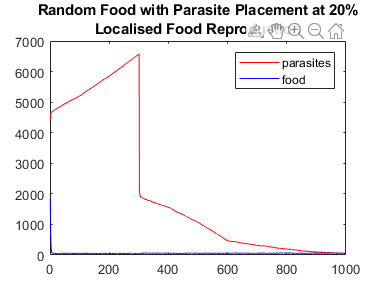

%% Results
% Food - Extinct
% Parasites - Extinct
t = 1:1:size(p19, 2);
figure;
plot(t, p19, 'r');
hold on
plot(t, f19, 'b');
legend('parasites', 'food');
title({'Random Food with Parasite Placement at 20%'; 'Localised Food Reproduction'});